## Jumping Spherical

A ball is released at rest and falls onto the ground. There is air resistance acting on the ball and its impact with the ground causes it to experience a stopping force in the direction opposite to its motion.

The force F_AR represents the air resistance force and the force F_c represents the force of the ground on the ball as it bounces off it.

The equations used are as follows:


$$F_m =F_G -F_{\textrm{AR}} -F_C$$



$$F_{\textrm{AR}} =k_{\textrm{AR}} {v_m }^2 \textrm{sign}\left(v_m \right)$$



$$F_C =\mathrm{ch}=c\left(h_0 -s\right)$$


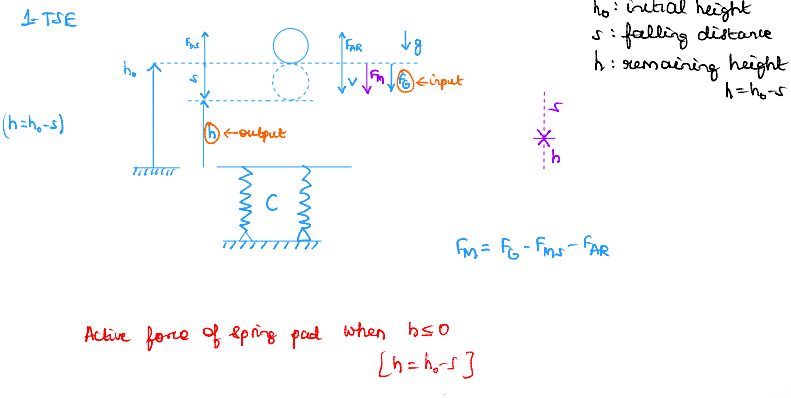

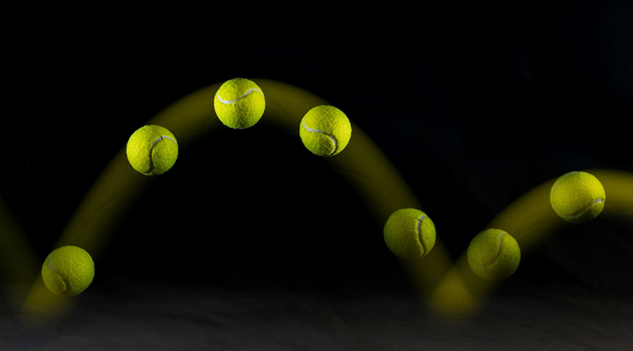

## Declaring Variables

% h represents the height of the ball above the ground: h = h_0 - s
% where s is the displacement of the ball from its dropoff position
simtime = 3;     
g = 9.81;               % acceleration due to gravity in N/kg
m = 0.1;                % mass in kg
h_0 = 1;                % drop off height in m
c = 10000;              % ground stiffness constant in N/m
                        % cannot be too low, else ball "goes below ground"
k_AR = 0.25;            % air resistance coefficient in N/(ms^-2)

## Simulation and Behaviour Plot

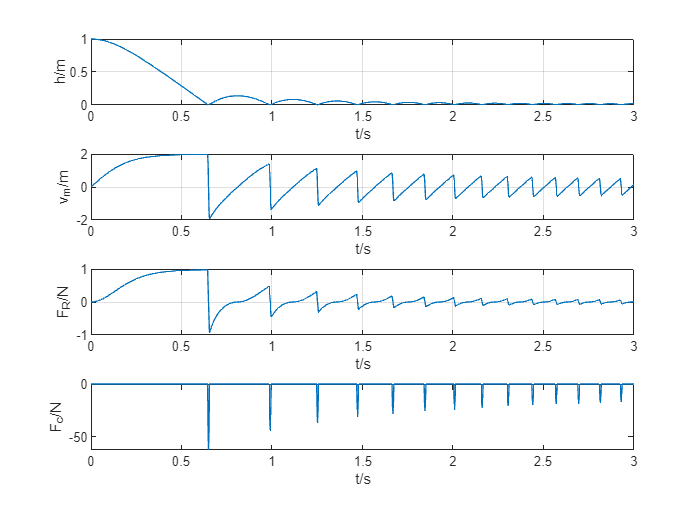

sim('Jumping_Spherical_System.slx')
figure
subplot(4, 1, 1)
plot(h.time, h.data)
grid on
xlabel('t/s')
ylabel('h/m')

subplot(4, 1, 2)
plot(v_m.time, v_m.data)
grid on
xlabel('t/s')
ylabel('v_m/m')

subplot(4, 1, 3)
plot(F_AR.time, F_AR.data)
grid on
xlabel('t/s')
ylabel('F_A_R/N')

subplot(4, 1, 4)
plot(F_c.time, F_c.data)
grid on
xlabel('t/s')
ylabel('F_c/N')